# Read Doric File

Three possible options on how you can implement this code for your data analysis:

- Open [MATLAB Online](https://matlab.mathworks.com/), upload there this notebook and Console_Acq_0000.doric. Then follow the steps of the notebook.

- Download this notebook and Console_Acq_0000.doric to your computer. Then follow the steps of the notebook.

- Open file with one of the first 2 options and copy parts of this code to your matlab code.

### Set file path

Edit the following cell with your file path:

filename = '/MATLAB Drive/readDoric/Console_Acq_0000.doric';

### Print all file tree (optional)

This allows you to identify the file path of each dataset of interest and its associated time vector. But Feel free to skip this step, since you can check the file structure in the Doric File Editor of DNS software.

h5disp(filename, '/', 'min');

HDF5 Console_Acq_0000.doric 
Group '/' 
    Group '/Configurations' 
        Group '/Configurations/FPConsole' 
            Group '/Configurations/FPConsole/AIN01' 
                Group '/Configurations/FPConsole/AIN01/GraphSettings' 
                Group '/Configurations/FPConsole/AIN01/Settings' 
            Group '/Configurations/FPConsole/AOUT01' 
                Group '/Configurations/FPConsole/AOUT01/GraphSettings' 
                Group '/Configurations/FPConsole/AOUT01/Modulations' 
                    Group '/Configurations/FPConsole/AOUT01/Modulations/Modulation1' 
                Group '/Configurations/FPConsole/AOUT01/Settings' 
            Group '/Configurations/FPConsole/GlobalSettings' 
            Group '/Configurations/FPConsole/SavingSettings' 
    Group '/DataAcquisition' 
        Group '/DataAcquisition/FPConsole' 
            Group '/DataAcquisition/FPConsole/Signals' 
                Group '/DataAcquisition/FPConsole/Signals/Series0001' 
                    Grou

Note that when using the Lock-In mode, the photometry demodulated signals have the following path naming: “DataAcquisition/FPConsole/Signals/Series#/AIN#xAOUT#-LockIn/Values” and associated Time vector: “DataAcquisition/FPConsole/Signals/Series#/AIN#xAOUT#-LockIn/Time”

### Load signal

Check the file structure and pick the signals you would like to load. Paste the paths to selected datasets

signal = h5read(filename,'/DataAcquisition/FPConsole/Signals/Series0003/AnalogIn/AIN01');
time   = h5read(filename,'/DataAcquisition/FPConsole/Signals/Series0003/AnalogIn/Time');

### Plot loaded signal

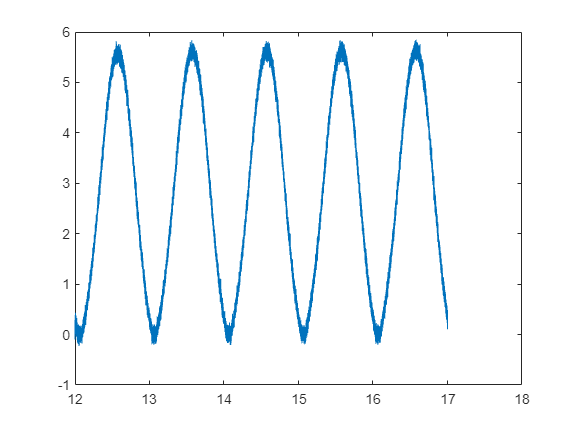

plot(time, signal);

Learn more about [HDF5 MATLAB library](https://www.mathworks.com/help/matlab/hdf5-files.html?s_tid=srchbrcm).